# Chapter 13 ATAP Exercises

## Equispaced Points, Runge Phenomenon

#### Mason Mault June 2025

Worked Exercises:

Exercise 13.1 Three examples

Exercise 13.2 Computing geometric means in Chebfun

Exercise 13.3 Borderline Convergence 

**Exercise 13.1 Three examples**

Draw plots comparing the accuracy of equispaced and Chebyshev interpolants as functions of n for $\exp \left(x^2 \right),\exp \left(-x^2 \right),$and $\exp \left(-1/x^2 \right)$.

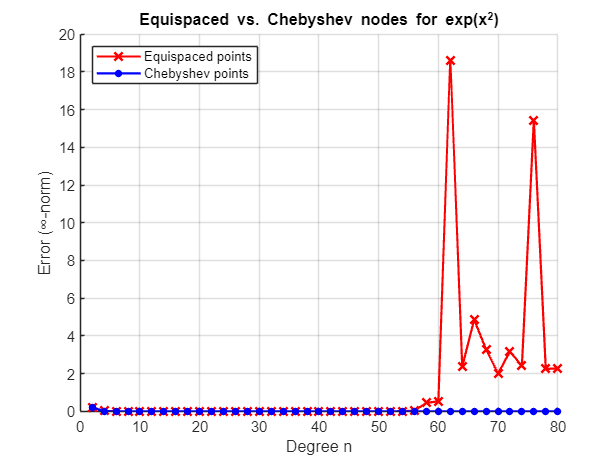

f1 = chebfun(@(x) exp(x.^2));

eequi1 = [];
echeb1 = [];
nn = 2:2:80;

for n = nn
    s = linspace(-1, 1, n+1);
    pequi1 = chebfun.interp1(s, f1);
    eequi1 = [eequi1 norm(f1 - pequi1, inf)];
    pcheb1 = chebfun(f1, n+1);
    echeb1 = [echeb1 norm(f1 - pcheb1, inf)];
end

figure
hold on
%semilogy(nn, 2.^(nn), '--r', 'LineWidth', 1.5)
semilogy(nn, eequi1, 'x-r', 'MarkerSize', 8, 'LineWidth', 1.5)
semilogy(nn, echeb1, '.-b', 'MarkerSize', 15, 'LineWidth', 1.5)
grid on
xlabel('Degree n')
ylabel('Error (∞-norm)')
legend('Equispaced points', 'Chebyshev points', 'Location', 'northwest')
title('Equispaced vs. Chebyshev nodes for exp(x^2)')

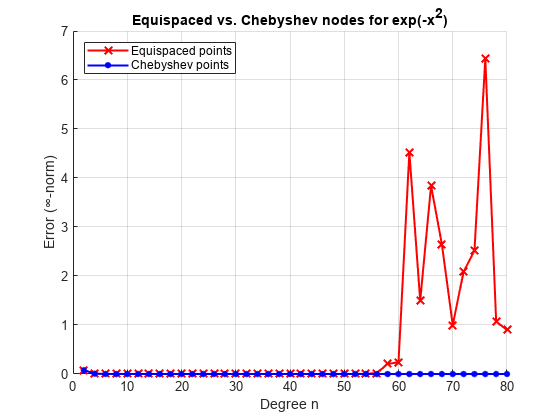

f2 = chebfun(@(x) exp(-x.^2));

eequi2 = [];
echeb2 = [];
nn = 2:2:80;

for n = nn
    s = linspace(-1, 1, n+1);
    pequi2 = chebfun.interp1(s, f2);
    eequi2 = [eequi2 norm(f2 - pequi2, inf)];
    pcheb2 = chebfun(f2, n+1);
    echeb2 = [echeb2 norm(f2 - pcheb2, inf)];
end

figure
hold on
semilogy(nn, eequi2, 'x-r', 'MarkerSize', 8, 'LineWidth', 1.5)
semilogy(nn, echeb2, '.-b', 'MarkerSize', 15, 'LineWidth', 1.5)
grid on
xlabel('Degree n')
ylabel('Error (∞-norm)')
legend('Equispaced points', 'Chebyshev points', 'Location', 'northwest')
title('Equispaced vs. Chebyshev nodes for exp(-x^2)')

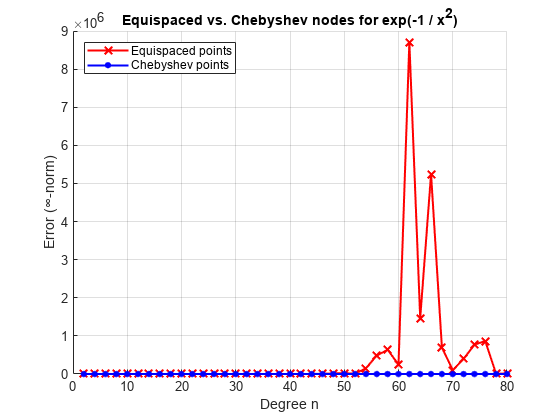

f3 = chebfun(@(x) exp(-1 / x.^2));

eequi3 = [];
echeb3 = [];
nn = 2:2:80;

for n = nn
    s = linspace(-1, 1, n+1);
    pequi3 = chebfun.interp1(s, f3);
    eequi3 = [eequi3 norm(f3 - pequi3, inf)];
    pcheb3 = chebfun(f3, n+1);
    echeb3 = [echeb3 norm(f3 - pcheb3, inf)];
end

figure
hold on
%semilogy(nn, 2.^(nn), '--r', 'LineWidth', 1.5)
semilogy(nn, eequi3, 'x-r', 'MarkerSize', 8, 'LineWidth', 1.5)
semilogy(nn, echeb3, '.-b', 'MarkerSize', 15, 'LineWidth', 1.5)
grid on
xlabel('Degree n')
ylabel('Error (∞-norm)')
legend('Equispaced points', 'Chebyshev points', 'Location', 'northwest')
title('Equispaced vs. Chebyshev nodes for exp(-1 / x^2)')

**Exercise 13.2 Computing geometric means in Chebfun**

Run and interpret the following code

x = chebfun('x', [0 1]);
f = chebfun(@(y) prod(abs(x - 1i*y)), [0.1 1]);
roots(f-2 / exp(1))

ans = 0.5255

**Interpretation:** This code finds the imaginary height $y$ in the complex plane where the geometric mean distance from the point $i\;y$ to the interval [0,1] is exactly $2/e$.

The height returned is 0.5255, exactly the value of the level curve enclosing the Runge region. Functions that are analytically continuable to the Runge region in the complex plane have (theoretically) favorable convergence properties.

The Runge region shown on page 99 of ATAP is reproduced below

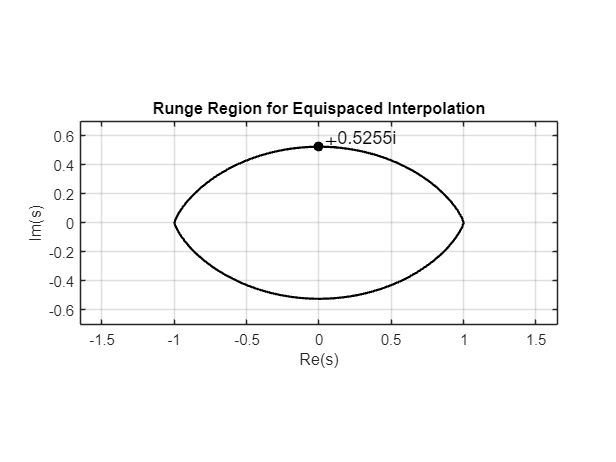

x4 = -1.65:.02:1.65;
y4 = -0.7:.02:0.7;
[xx4, yy4] = meshgrid(x4, y4);
ss4 = xx4 + 1i*yy4;
u = @(s) -1 + 0.5*real((s+1).*log(s+1) - (s-1).*log(s-1));

figure
contour(x4, y4, u(ss4), (-1 + log(2)) * [1 1], 'k', 'LineWidth', 1.5)
hold on

plot(1i * 0.5255, 'k.', 'MarkerSize', 20) 
text(0.03, 0.57, '\pm0.5255i', 'FontSize', 12)  

axis equal
xlabel('Re(s)')
ylabel('Im(s)')
title('Runge Region for Equispaced Interpolation')
grid on

**Exercise 13.3 Borderline Convergence**

In the text it was claimed equispaced polynomial interpolants on [-1, 1] converge for $f_{\textrm{conv}} \left(x\right)={\left(1+{\left(x/0\ldotp 53\right)}^2 \right)}^{-1}$and diverge for $f_{\textrm{div}} \left(x\right)={\left(1+{\left(x/0\ldotp 52\right)}^2 \right)}^{-1}$. The goal of this exercises is to probe this numerically.

Theoretically, convergence is expected for $f_{\textrm{conv}}$ and not $f_{\textrm{div}}$ due to the location of their poles with respect to the Runge region. As shown below, in practice, $f_{\textrm{conv}}$ also falls short.

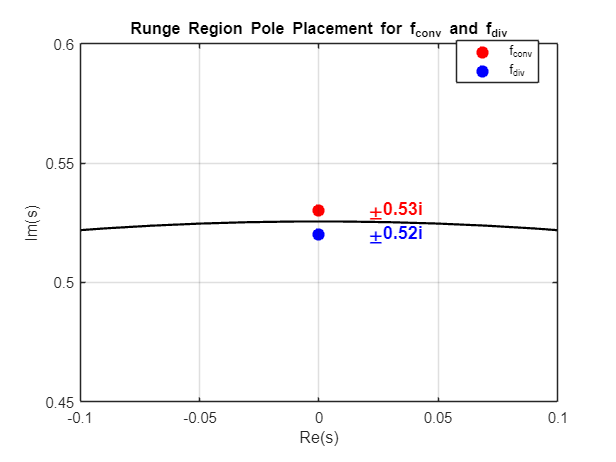

figure
contour(x4, y4, u(ss4), (-1 + log(2)) * [1 1], 'k', 'LineWidth', 1.5)
hold on

% poles of fConv aand fDiv
poleConv = plot(1i * 0.53, 'r.', 'MarkerSize', 25); 
poleDiv = plot(1i * 0.52, 'b.', 'MarkerSize', 25); 

text(0.02, 0.53, '\pm0.53i', 'Color', 'r', 'FontSize', 12, 'FontWeight', 'bold')
text(0.02, 0.52, '\pm0.52i', 'Color', 'b', 'FontSize', 12, 'FontWeight', 'bold')

axis equal
xlabel('Re(s)')
ylabel('Im(s)')
title('Runge Region Pole Placement for f_{conv} and f_{div}')
grid on

% zoom in around poles
xlim([-0.1, 0.1])
ylim([0.45, 0.6])

legend([poleConv, poleDiv], {'f_{conv}', 'f_{div}'}, 'Location', 'best')

Below, error curves are computed for interpolants through both equispaced and Chebyshev points, as well as the associated Lebesgue constants.

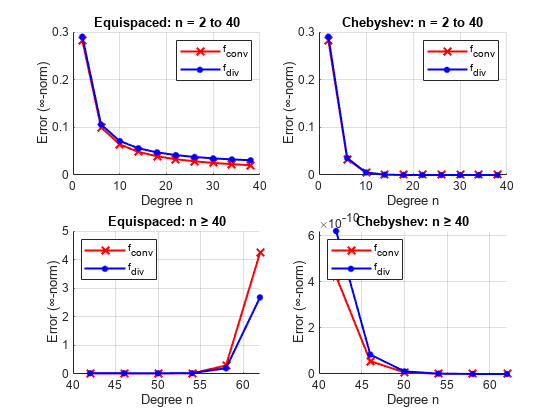

fConv = chebfun(@(x) (1 + (x/0.53)^2)^(-1));
fDiv = chebfun(@(x) (1 + (x/0.52)^2)^(-1) );

nn = 2:4:65;
eConv = zeros(size(nn));
eDiv = eConv;
eConvCheb = eDiv;
eDivCheb = eDiv;
lebs = eDiv;
lebsCheb = eDiv;

for i = 1:length(nn)
    n = nn(i);
    % equispaced nodes
    s = linspace(-1, 1, n+1);
    % chebyshev nodes for comparison
    s2 = chebpts(n + 1);
    % compute interpolants and errors
    pConv = chebfun.interp1(s, fConv);
    pDiv = chebfun.interp1(s, fDiv);
    pConvCheb = chebfun(fConv, n + 1);
    pDivCheb = chebfun(fDiv, n + 1);
    % append errors and Lebesgue constants
    eConv(i) = norm(fConv - pConv, inf);
    eDiv(i) = norm(fDiv - pDiv, inf);
    eConvCheb(i) = norm(fConv - pConvCheb, inf);
    eDivCheb(i) = norm(fDiv - pDivCheb, inf);
    [L,lebs(i)] = lebesgue(s);
    [L2, lebsCheb(i)] = lebesgue(s2);
end

figure

% equispaced low degree
subplot(2,2,1)
hold on
idx1 = nn <= 40;
semilogy(nn(idx1), eConv(idx1), 'x-r', 'MarkerSize', 8, 'LineWidth', 1.5)
semilogy(nn(idx1), eDiv(idx1), '.-b', 'MarkerSize', 15, 'LineWidth', 1.5)
grid on
xlabel('Degree n')
ylabel('Error (∞-norm)')
title('Equispaced: n = 2 to 40')
legend('f_{conv}', 'f_{div}', 'Location', 'northeast')

% chebfun low degree
subplot(2,2,2)
hold on
semilogy(nn(idx1), eConvCheb(idx1), 'x-r', 'MarkerSize', 8, 'LineWidth', 1.5)
semilogy(nn(idx1), eDivCheb(idx1), '.-b', 'MarkerSize', 15, 'LineWidth', 1.5)
grid on
xlabel('Degree n')
ylabel('Error (∞-norm)')
title('Chebyshev: n = 2 to 40')
legend('f_{conv}', 'f_{div}', 'Location', 'northeast')

% equispaced high degree
subplot(2,2,3)
hold on
idx2 = nn >= 40;
semilogy(nn(idx2), eConv(idx2), 'x-r', 'MarkerSize', 8, 'LineWidth', 1.5)
semilogy(nn(idx2), eDiv(idx2), '.-b', 'MarkerSize', 15, 'LineWidth', 1.5)
grid on
xlabel('Degree n')
ylabel('Error (∞-norm)')
title('Equispaced: n ≥ 40')
legend('f_{conv}', 'f_{div}', 'Location', 'northwest')

% chebfun high degree
subplot(2,2,4)
hold on
semilogy(nn(idx2), eConvCheb(idx2), 'x-r', 'MarkerSize', 8, 'LineWidth', 1.5)
semilogy(nn(idx2), eDivCheb(idx2), '.-b', 'MarkerSize', 15, 'LineWidth', 1.5)
grid on
xlabel('Degree n')
ylabel('Error (∞-norm)')
title('Chebyshev: n ≥ 40')
legend('f_{conv}', 'f_{div}', 'Location', 'northwest')

We see $f_{\textrm{conv}}$ has smaller error than $f_{\textrm{div}}$ until $n$ reaches around 55, where both errors spike. The errors of $f_{\textrm{conv}}$ for both points sets are shown below, as well as the point sets Lebesgue constant.

T = table(...
    nn(:), round(lebs(:), 4), round(lebsCheb(:), 4), eConv(:), eConvCheb(:), ...
    'VariableNames', {'Degree_n', 'Lebesgue_Equispaced', 'Lebesgue_Chebyshev', 'Error_Conv_Equispaced', 'Error_Conv_Chebyshev'});

disp(T)

    Degree_n    Lebesgue_Equispaced    Lebesgue_Chebyshev    Error_Conv_Equispaced    Error_Conv_Chebyshev
    ________    ___________________    __________________    _____________________    ____________________

        2                 1.25                 1.25                 0.28271                   0.28271     
        6               4.5493               2.0826                0.099789                  0.033283     
       10                 29.9                2.421                0.064314                 0.0048455     
       14               283.21               2.6388                0.048454                 0.0006126     
       18               3171.4               2.8003                0.039233                8.3601e-05     
       22                38672               2.9288                0.033111     

Interpolation points equally spaced in distance are often inferior to interpolation points equally spaced in angle.